# **ACTIVITY 1**

## **simulating a basic end to end digital communication link with AWGN **

# **Tx------>channel----->Rx**

# **source bits---->QAM mod---->**

# ***Generating source bits***

clc
close
clear
numBits = 2e4; %number of source bits 0 and 1s for Txion 20,000
srcBits = randi([0 1],numBits,1); %column vector of random digital bits

16-QAM is a common single-carrier modulation scheme. It maps 4 input bits to one of 16 complex numbers, called *symbols*. For each complex-valued symbol, the real and imaginary parts represent the in-phase and quadrature components, respectively, of a waveform.

The "16" in 16-QAM is the *modulation order*. It's useful to store the modulation order in a variable so that it can be used throughout your simulation.

modOrder = 16; % Modulation Order

The `qammod` function creates a modulated QAM signal from an input sequence.

`y` `=` `qammod``(``x``,``modOrder``)`

The modulated signal `y` is a sequence of QAM symbols—or, in MATLAB terms, a vector of complex numbers.

When the input sequence is made up of bits, set `"InputType"` to `"bit"`.

`y` `=` `qammod``(``x``,``modOrder``,``"InputType"``,``"bit"``)`

modOut = qammod(srcBits,modOrder,"InputType","bit");

You can look at the constellation of the modulated QAM signal by using the `scatterplot` function. This function plots the imaginary part (quadrature) vs. the real part (in-phase) of each complex-valued QAM symbol.

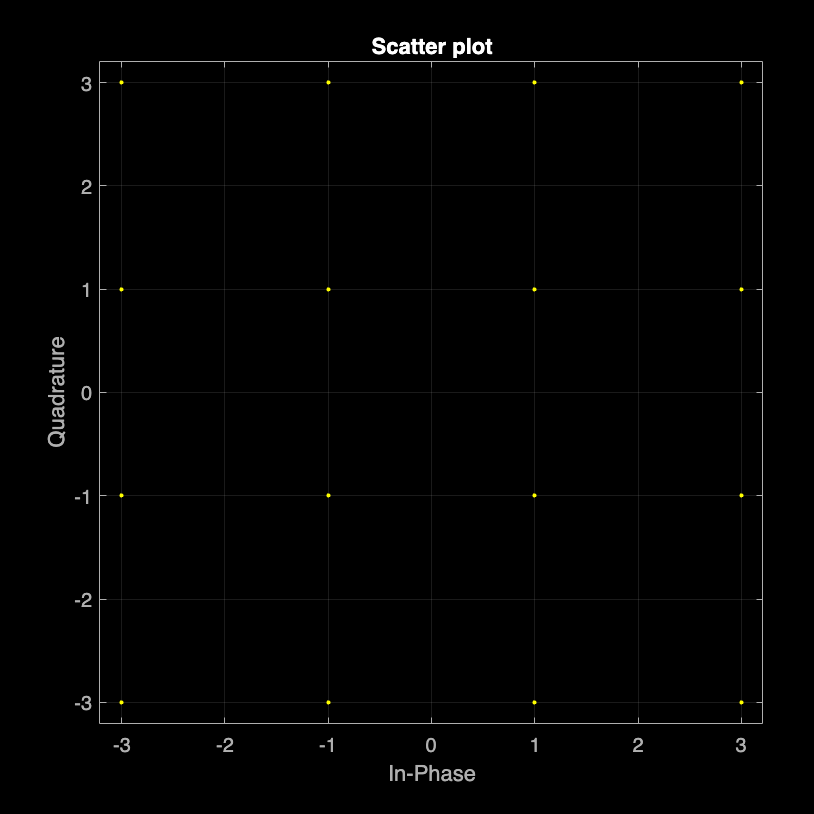

scatterplot(modOut)
grid on

What you see in the scatter plot is the ideal 16-QAM constellation—16 complex-valued symbols arranged in a square, with each symbol equally spaced from its neighbors. The greater the separation between points, the better the error rate performance. Later, when you add noise to the simulation, you'll see the received observations depart from this ideal configuration.

## ***No Channel:***

For now, the simulation assumes that the modulated signal is unchanged when it's received by the receiver.

chanOut = modOut;

##  Receiver

Demodulation turns the 16-QAM symbols back into bits.

Use the `qamdemod` function to demodulate the received signal. It has almost the same syntax as `qammod`. The only difference is that `qamdemod` specifies the `"OutputType"`.

`z` `=` `qamdemod``(``y``,``modOrder``,``"OutputType"``,``"bit"``)`

The output `z` is a column vector of 1s and 0s—the received bits.

demodOut = qamdemod(chanOut,modOrder,"OutputType","bit");

Since the 16-QAM signal was not subject to any channel effects, the received bits should match the source bits exactly.

To see if the two vectors are identical, use the `isequal` function.

`check` `=` `isequal``(``x1``,``x2``)`

The output `check` is a logical variable with value 1 if the two vectors are identical and 0 if they are not.

check = isequal(srcBits,demodOut)

check = logical
   1


A common corruption, or noise source, in the received signal is due to electron motion from the electronics in the receiver. This noise is modeled as part of the channel.

The noise is called *additive white Gaussian noise*, or AWGN, because it's typically *added* to the signal, has a flat (or *white*) spectral density, and has a *Gaussian* probability density function.

In this activity, you'll add noise to your 16-QAM link simulation and note its effects.

## **AWGN Channel**

The `awgn` function applies additive white Gaussian noise (AWGN) to its input signal. The amount of noise added is specified as a signal-to-noise ratio, assuming the input signal has an average power of 1.

Fortunately, you can tell the `qammod` function to output a signal with an average power of 1. Simply set `"UnitAveragePower"` to `true`.

`sigOut` `=` `qammod``(``bits``,``modOrder``,``...`

    `"InputType"``,``"bit"``,``...`

    `"UnitAveragePower"``,``true``)`

*Pro tip**: Have you ever had trouble reading a long line of code? You can use* `...` *to split a long command into multiple lines.*

modOut4AWGN = qammod(srcBits,modOrder,"InputType","bit","UnitAveragePower",true);

Next, model the noisy channel by applying AWGN to the modulated signal.

You can use the `awgn` function to apply AWGN to a signal. The noise power added is specified as a signal-to-noise ratio, `SNR`, measured in decibels (dB).

`SNR` `=` `7`  `% dB`

`sigOut` `=` `awgn``(``sig``,``SNR``)`

SNR = 15;
chanOut = awgn(modOut4AWGN,SNR);

To see the impact of the noise, you can view the constellation of the channel output using the `scatterplot` function, as before.

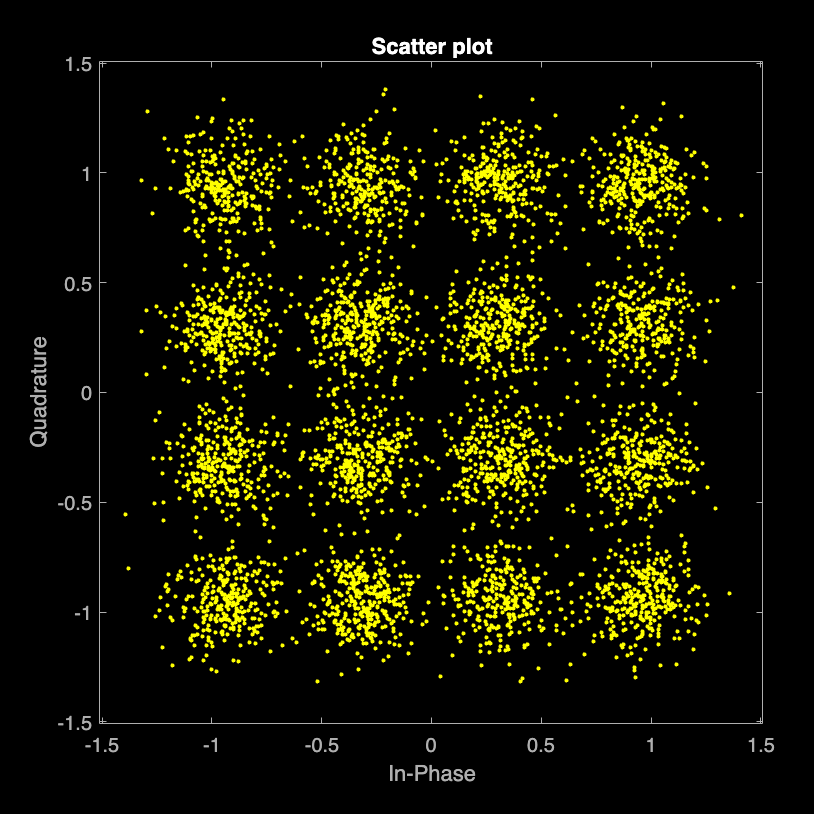

scatterplot(chanOut)

Now you can see that the noise has perturbed the symbols from their ideal values.

The `qamdemod` function uses a nearest-neighbor decision rule to map received observations back to the nearest ideal symbol constellation point. If an observation has been perturbed too much, it will get mapped to the wrong point. This results in symbol errors, in turn yielding bit errors.

Since you set `"UnitAveragePower"` when you called `qammod`, you must also set it in `qamdemod`.

`sigOut` `=` `qamdemod``(``sig``,``modOrder``,``...`

    `"OutputType"``,``"bit"``,``...`

    `"UnitAveragePower"``,``true``)`

demodOut = qamdemod(chanOut,modOrder,"OutputType","bit","UnitAveragePower",true);
check = isequal(demodOut,srcBits)

check = logical
   0


This time, the source bits and received bits do not match.

Try increasing and decreasing the value of `SNR`. How does it impact the scatter plot?

The source bits are randomly generated, so each time you run the script they will be different. How large do you have to set `SNR` for the source and received bits to match consistently?

You can do a quick check to see if your link is operating correctly without noise by increasing `SNR` to a large number, like 100. This effectively removes the noisy channel.

It's useful to know how many bit errors there are—there's a big difference between 5 bit errors and 5000 bit errors. In the next activity, you'll count bit errors and calculate the bit error rate (BER).

# Calculate the Bit Error Rate

Noise can introduce errors in the received bits. Comparing each bit sent to the corresponding bit received tells you if there are any errors. The fraction of bits that contain bit errors is a key way to measure the performance of a communications system.

Background

To count bit errors, you start by performing a bit-by-bit comparison of the source bits and the received bits.

The logical operator `~=` (not equal) compares two arrays element-by-element.

`isErr` `=` `x``~=``z`

The output `isErr` is a logical array. It has the value 1 where the elements of `x` and `z` are **not** equal and 0 where they are.

isBitError = srcBits ~= demodOut;
numBitErrors = nnz(isBitError) %counts the number of bit errors

numBitErrors = 103

The bit error rate (BER) is calculated by dividing the number of bit errors by the total number of bits.

BER = numBitErrors/numBits

BER = 0.0052

The BER of 0.0043 means that 0.43% of the received bits do not match the source bits. Try increasing and decreasing the value of `SNR`. How does it change the BER?

Right now, the transmitter output is a sequence of QAM symbols, but to transmit a signal over real-world channels, you need a time-domain signal. A pulse-shaping filter converts the sequence of symbols into a time-domain signal using weighted, regularly-spaced pulses. In the next activity, you'll add pulse-shaping filters to the transmitter and receiver.

In this activity, you'll add square-root raised cosine filters to the transmitter and receiver. The transmit filter takes the 16-QAM signal as input, and its output is sent over the channel. The receive filter takes the channel output as its input, and its output is passed to the QAM demodulator.

## **Background**

Because systems typically use matched filters, it's common to create the transmit and receive filters at the same time.

You can create a square-root raised cosine transmit filter using the following syntax.

`txFilt` `=` `comm.RaisedCosineTransmitFilter`

A similar syntax creates the matched receive filter.

`rxFilt` `=` `comm.RaisedCosineReceiveFilter`

These syntaxes set the filter properties to default values. If you leave off the semicolon, you can see some of the properties in the output panel. **For example, the property **`OutputSamplesPerSymbol`** has the default value 8, which means the filter upsamples the signal so it has 8 samples for each QAM symbol.**

txFilt = comm.RaisedCosineTransmitFilter

txFilt =   comm.RaisedCosineTransmitFilter with properties:

                     Shape: 'Square root'
             RolloffFactor: 0.2000
       FilterSpanInSymbols: 10
    OutputSamplesPerSymbol: 8
                      Gain: 1


rxFilt = comm.RaisedCosineReceiveFilter

rxFilt =   comm.RaisedCosineReceiveFilter with properties:

                    Shape: 'Square root'
            RolloffFactor: 0.2000
      FilterSpanInSymbols: 10
    InputSamplesPerSymbol: 8
         DecimationFactor: 8
         DecimationOffset: 0
                     Gain: 1


To apply the transmit filter to the modulated 16-QAM signal, pass the signal as an input to the stored filter.

`sigOut` `=` `txFilt``(``sig``)`

txFiltOut = txFilt(modOut4AWGN)

txFiltOut =   -0.0057 - 0.0019i
  -0.0049 - 0.0016i
  -0.0028 - 0.0009i
   0.0004 + 0.0001i
   0.0041 + 0.0014i
   0.0075 + 0.0025i
   0.0100 + 0.0033i
   0.0106 + 0.0035i
   0.0035 + 0.0088i
   0.0006 + 0.0067i


**Notice that **`txFiltOut`** is 8 times longer than **`modOut`, which is expected given the value of the filter property `OutputSamplesPerSymbol`.

Next, you want to apply AWGN to the filtered signal. However, the transmit filter changed the signal power. 

**To scale the noise power appropriately, pass a third input to the **`awgn`** function.**

`sigOut` `=` `awgn``(``sig``,``SNR``,``"measured"``)`

*When you use the *`"measured"`* option, the function calculates the input signal power and scales the noise power based on the signal-to-noise ratio.*

SNR = 7;
chanOut = awgn(txFiltOut,SNR,"measured")

chanOut =    0.0758 - 0.0389i
  -0.0715 + 0.1453i
  -0.1630 - 0.1253i
  -0.1158 + 0.1854i
  -0.0986 + 0.0462i
   0.1851 + 0.0596i
  -0.1099 + 0.1139i
  -0.2013 + 0.0158i
  -0.2135 - 0.0406i
  -0.2229 + 0.0711i


Now apply the receive filter to the signal. As with the transmit filter, pass the signal as an input to the stored filter.

rxFiltOut = rxFilt(chanOut)

rxFiltOut =   -0.0005 + 0.0002i
  -0.0004 + 0.0015i
   0.0007 - 0.0034i
  -0.0069 + 0.0079i
   0.0264 - 0.0181i
  -0.1125 + 0.0787i
  -0.1534 + 0.0926i
   0.2065 + 0.0386i
   0.0077 + 0.0014i
   0.1114 - 0.0211i


Demodulate back into bits. This code only executes after rxFiltOut has been created.

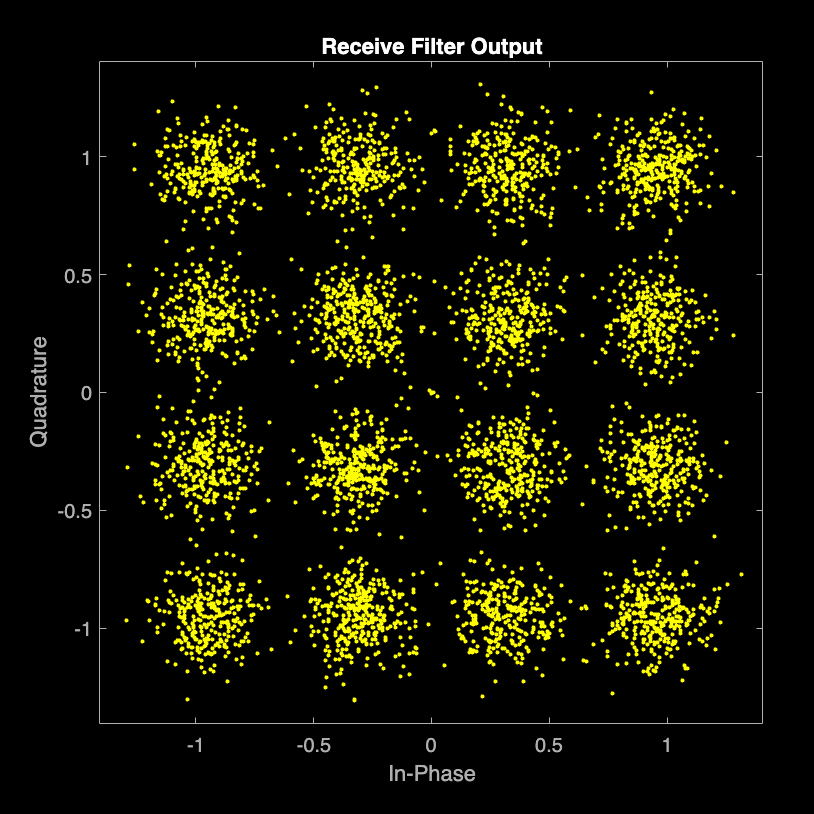

if exist("rxFiltOut","var")  
    scatterplot(rxFiltOut)
    title("Receive Filter Output")
    demodOut = qamdemod(rxFiltOut,modOrder,"OutputType","bit","UnitAveragePower",true);
end

## Further Practice

Remember you added more noise to the channel here (SNR of 7 dB) compared to the previous activity (SNR of 15 dB). **The receive filter has reduced the noise power by about 8 dB, so the constellation has roughly the same amount of noise as the signal from the previous activity.**

It can be helpful to view the power spectra of both the noiseless filtered signal and the noisy signal. To do this, create a spectrum analyzer that displays the spectra of two signals.

specAn = dsp.SpectrumAnalyzer(...
    "NumInputPorts",2, ...
    "SpectralAverages",50,...
    "ShowLegend",true);

With the spectrum analyzer created, you can look at the spectra of the transmit filter output and the AWGN channel output. The noiseless signal is yellow, and the noisy signal is blue.

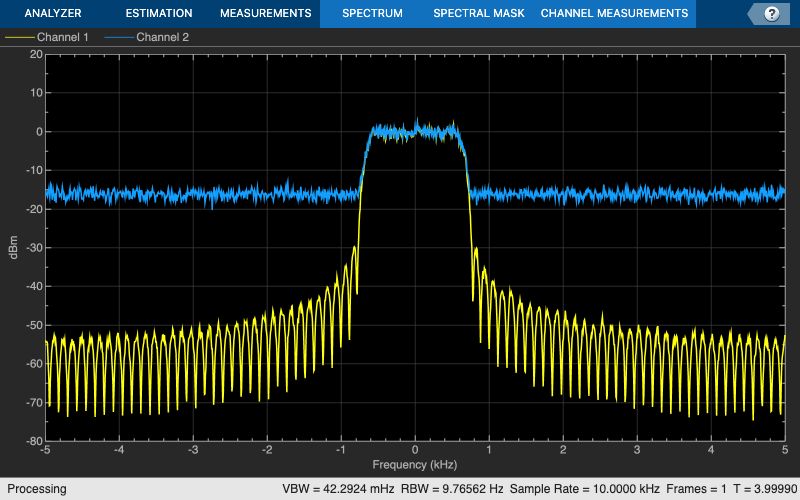

specAn(txFiltOut,chanOut)

The Spectrum Analyzer opens in a figure window. Close the figure to return to the live script.

You haven't yet examined the performance of the link by calculating the BER. You'll do this in the next activity